% -----------------------------------------------------------------------
% 1. System Definition and Simulation
% -----------------------------------------------------------------------

% Define system matrices (Eq. 17)
E = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 0];
A = [0 1 0 0; -2 -3 1 0; 0 0 1 0; 0 0 0 1];
B = [0; 1.818; 0; 4.545];
C = [1 0 0 0];
% Simulation parameters
omega = 1;
dt = 0.001;
t = 0:0.001:6;
u = sin(t);
% Residual function for ode15i0.001
f = @(t, x, dx) E*dx - A*x - B*sin(t);

x0 = zeros(4,1); 
dx0 = zeros(4,1);

% Use decic to find consistent initial conditions if needed
[x0, dx0] = decic(f, 0, x0, [0 0 0 0], dx0, [1 1 0 0]);

% Solve DAE
[t, x] = ode15i(f, t, x0, dx0);

% Output
y = C*x';

% -----------------------------------------------------------------------
% 2. Data Preparation: Training and Testing Sets
% -----------------------------------------------------------------------

% Split data into training and testing sets (as in the paper)
train_size = 2000;
test_size = length(t) - train_size;

t_train = t(1:train_size);
y_train = y(1:train_size)'; % Transpose to make it a row vector
u_train = u(1:train_size);

t_test = t(train_size+1:end);
y_test = y(train_size+1:end)'; % Transpose to make it a row vector
u_test = u(train_size+1:end);

% -----------------------------------------------------------------------
% 3. Input-Aware HAVOK Implementation (Training Phase)
% -----------------------------------------------------------------------

% HAVOK parameters (from the paper)
d = 4; % Embedding dimension
r = 4; % Rank truncation
lambda = 0.001; % Regularization parameter

% Construct Hankel matrix (Eq. 7)
H = hankel_matrix(y_train, d);

% Singular Value Decomposition (SVD) (Eq. 8)
[U, S, V] = svd(H);
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% Derivative approximation (Eq. 9)
Vr_dot = (Vr(3:end,:) - Vr(1:end-2,:))/(2*dt);
Vr = Vr(2:end-1,:);

% Calculate the amount of data removed from the original y_train
removedData = length(y_train) - size(Vr,1)+1;

%Truncate u_train
u_train_truncated = u_train(removedData-2:end-2);

% Library matrix construction (Eq. 11)
Theta = [Vr, u_train_truncated'];

% L1 Regularization using CVX
cvx_begin
    variable Xi(size(Theta, 2), size(Vr_dot, 2));  % Regression coefficients
    minimize( sum(norms(Vr_dot - Theta * Xi, 1, 1)) + lambda * norm(Xi, 1) );
cvx_end

 
Calling SDPT3 4.0: 16005 variables, 7984 equality constraints
------------------------------------------------------------

 num. of constraints = 7984
 dim. of socp   var  = 16000,   num. of socp blk  = 8000
 dim. of linear var  =  4
 dim. of free   var  =  1 *** convert ublk to lblk
 number of dense column in A = 20
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+00|8.8e+01|8.1e+07| 8.892497e+05  0.000000e+00| 0:0:00| spchol  1  1 
 1|1.000|0.517|2.0e-07|4.3e+01|5.1e+07| 1.138275e+06  6.793559e+03| 0:0:00| spchol  1  1 
 2|1.000|0.992|1.3e-07|6.0e-01|1.7e+06| 1.075613e+06  2.871167e+03| 0:0:00| spchol  1  


% Extract A_hat and B_hat (Eqs. 14-16)
A_hat = Xi(1:r, :)';
B_hat = Xi(end, :)';

% Find C_hat
C_hat = Ur(1,:)*Sr;

% E estimation
% Residual function for ode15i
f = @(t, x, dx) E*dx - A*x - B*sin(t);

% Initial conditions
x0 = zeros(4,1); 
dx0 = zeros(4,1);
[x0, dx0] = decic(f, 0, x0, [0 0 0 0], dx0, [1 1 0 0]);

% Solve DAE
[t, x] = ode15i(f, t_test, x0, dx0);
x = x';  % Transpose to [4 x T]
T = length(t_test);

% Estimate xdot by solving E*xdot = A*x + B*u numerically at each t_i
xdot = zeros(4, T);

% Options for fsolve
opts = optimoptions('fsolve', 'Display', 'none');

for i = 1:T
    xi = x(:,i);
    ui = u_test(i);

    % Define residual at time t(i)
    res = @(dx) E*dx - A_hat*xi - B_hat*ui;

    dx_guess = zeros(4,1);
    dx_sol = fsolve(res, dx_guess, opts);

    xdot(:,i) = dx_sol;
end

% Compute output y = Cx
y = C * x;

% Optional: Estimate E from simulated data
RHS = A_hat*x + B_hat*u_test;
E_est = zeros(4,4);
E_est(1:3,1:3) = RHS(1:3,:)*pinv(xdot(1:3,:));

disp('Estimated E:');

Estimated E:


disp(E_est)

    1.0000    0.0000   -0.0000         0
   -0.0000    1.0000   -0.0000         0
    0.0000    0.0000    1.0000         0
         0         0         0         0



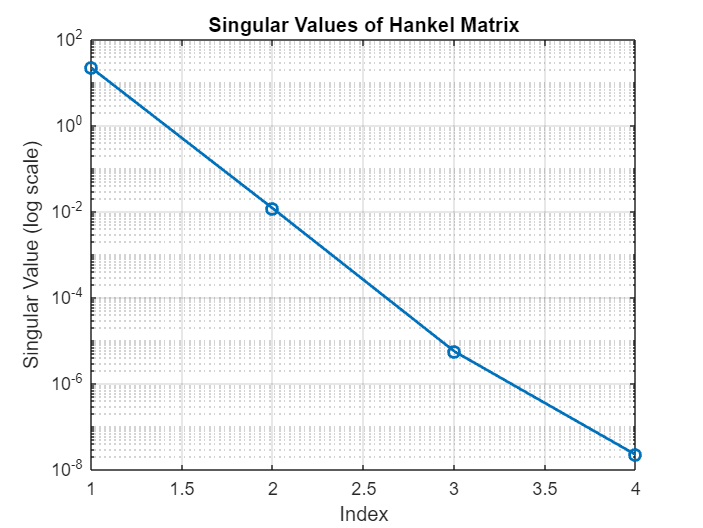

% Assuming your Hankel matrix is already computed and stored in variable H

% Compute SVD of the Hankel matrix
[U, S, V] = svd(H, 'econ');

% Extract singular values as a vector
singular_values = diag(S);

% Plot singular values on logarithmic scale to identify "elbow point"
figure;
semilogy(singular_values, 'o-', 'LineWidth', 1.5);
grid on;
title('Singular Values of Hankel Matrix');
xlabel('Index');
ylabel('Singular Value (log scale)');

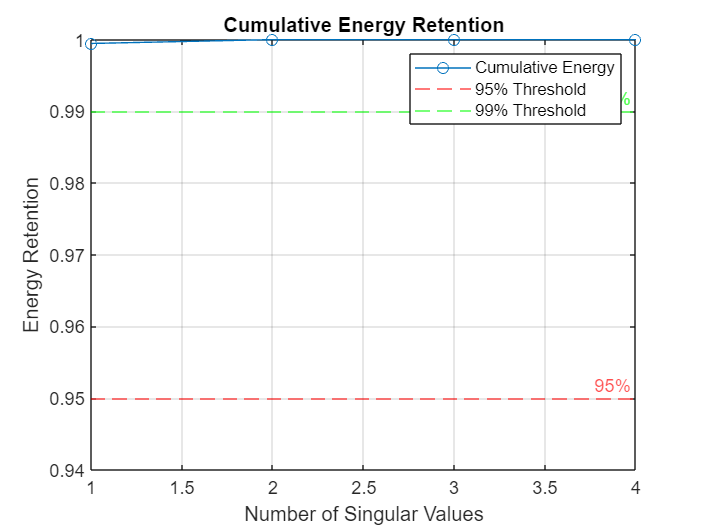


% Calculate energy retention for different ranks
total_energy = sum(singular_values);
cumulative_energy = cumsum(singular_values) / total_energy;

% Plot energy retention
figure;
plot(cumulative_energy, 'o-');
grid on;
title('Cumulative Energy Retention');
xlabel('Number of Singular Values');
ylabel('Energy Retention');
hold on;
yline(0.95, 'r--', '95%');
yline(0.99, 'g--', '99%');
legend('Cumulative Energy', '95% Threshold', '99% Threshold');


% Find optimal ranks
rank_95 = find(cumulative_energy >= 0.95, 1);
rank_99 = find(cumulative_energy >= 0.99, 1);

fprintf('Rank for 95%% energy retention: %d\n', rank_95);

Rank for 95% energy retention: 1


fprintf('Rank for 99%% energy retention: %d\n', rank_99);

Rank for 99% energy retention: 1


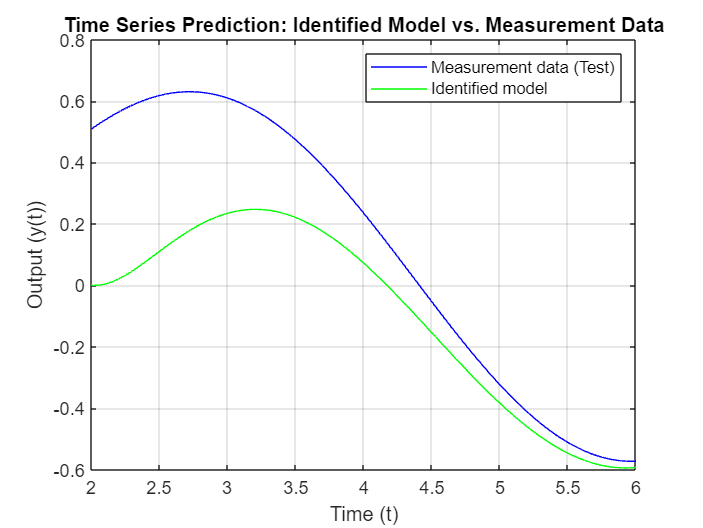

% -----------------------------------------------------------------------
% 4. Model Validation (Testing Phase)
% -----------------------------------------------------------------------

% Initial condition for test phase, which must be a vector of size r
v0 = Vr(end,:)'; % Use the last state from training data as initial condition

% Create a state-space model from the identified matrices
A_hat_sys = A_hat;
B_hat_sys = B_hat;
C_hat_sys = C_hat;
E_hat_sys = E_est; 

f = @(t, x, dx) E_hat_sys*dx - A_hat_sys*x - B_hat_sys*sin(t);

x0 = zeros(4,1); 
dx0 = zeros(4,1);

% Use decic to find consistent initial conditions if needed
[x0, dx0] = decic(f, 0, x0, [0 0 0 0], dx0, [1 1 0 0]);

% Solve DAE
[T_hat, x] = ode15i(f, t_test, x0, dx0);

% Output
y_hat = C_hat_sys*x';
% -----------------------------------------------------------------------
% 5. Plotting the Results
% -----------------------------------------------------------------------

% Correct the sizes of y_test and y_hat
min_length = min(length(y_test), length(y_hat));
y_test_resized = y_test(1:min_length);
y_hat_resized = y_hat(1:min_length);
T_hat_resized = T_hat(1:min_length);
t_test_resized = t_test(1:min_length);

% Plot time series comparison
figure;
plot(t_test_resized, y_test_resized, 'b', 'DisplayName', 'Measurement data (Test)'); % measurement data
hold on; % Hold on, means that the next plot is added to the existing axes
plot(T_hat_resized, y_hat_resized, 'g', 'DisplayName', 'Identified model'); % identified model
xlabel('Time (t)');
ylabel('Output (y(t))');
title('Time Series Prediction: Identified Model vs. Measurement Data');
legend('show');
grid on;
hold off; % 


% Calculate error between predicted and actual time series
error = y_test_resized - y_hat_resized;

% Display some error values for inspection (DEBUGGING)
disp('First 10 error values:');

First 10 error values:


disp(error(1:10));

    0.5086    0.5089    0.5092    0.5095    0.5098    0.5101    0.5105    0.5108    0.5111    0.5114



disp('Size of error vector:');

Size of error vector:


disp(size(error));

        4001        4001



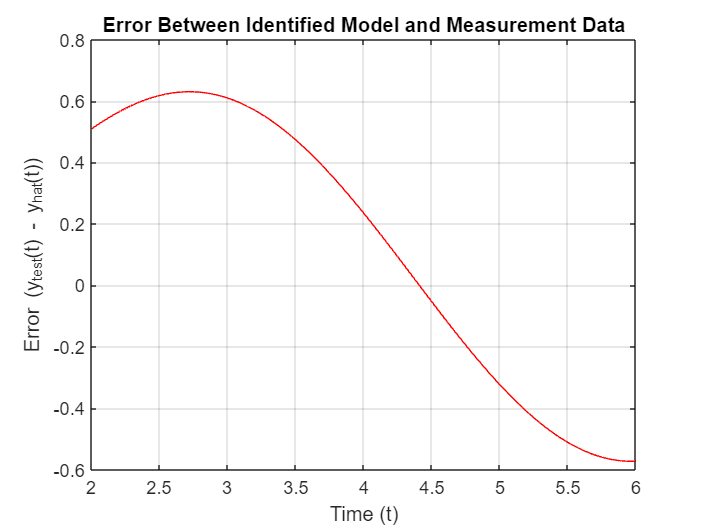


% Plot error between predicted and actual time series
figure;
hold off; %Force hold off
plot(T_hat_resized, error(1:min_length), '-r', 'DisplayName', 'Error');  % Explicit line plot
xlabel('Time (t)');
ylabel('Error (y_{test}(t) - y_{hat}(t))');
title('Error Between Identified Model and Measurement Data');
% legend('show');
grid on;

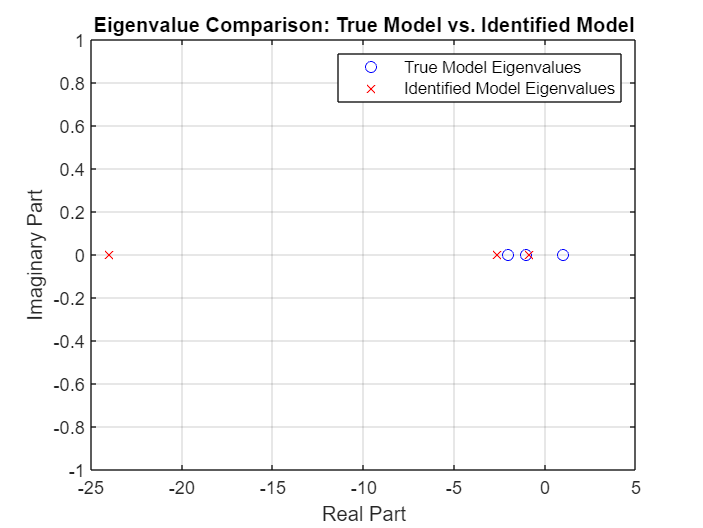



% -----------------------------------------------------------------------
% 6. Eigenvalue Analysis
% -----------------------------------------------------------------------

% Eigenvalues of the original matrix A
eigenvalues_A = eig(A,E);

% Eigenvalues of the identified matrix A_hat
eigenvalues_A_hat = eig(A_hat,E_est);

% Plot eigenvalues
figure;
plot(real(eigenvalues_A), imag(eigenvalues_A), 'bo', 'DisplayName', 'True Model Eigenvalues');
hold on;
plot(real(eigenvalues_A_hat), imag(eigenvalues_A_hat), 'rx', 'DisplayName', 'Identified Model Eigenvalues');
xlabel('Real Part');
ylabel('Imaginary Part');
title('Eigenvalue Comparison: True Model vs. Identified Model');
legend('show');
grid on;
hold off;

function H = hankel_matrix(y, d)
    % y: time series data (row vector)
    % d: embedding dimension
    k = length(y);
    p = k - d+1;
    H = zeros(d, p);
    for i = 1:d
        H(i,:) = y(i:i+p-1);
    end
end
%The difference in scaling stems from the orthonormalization of the modes during the SVD in the third step of the HAVOK algorithm... Unfortunately, it is not as straightforward to regain this difference in amplitude for the final HAVOK model time series. Integrating a correction for this effect would be an interesting point for future research
%Other potential issues that could contribute to your amplitude discrepancy:

%Initial conditions - especially if your measurement data contains significant transients

%Measurement time length - affecting the ratio of transient to steady-state motion

%Chosen measurement degree of freedom - if it doesn't adequately capture all modes

%Nonlinearity handling - HAVOK treats nonlinearities as intermittent forcing events, which might not fully capture amplitude effects

%Your case appears to be a classic example of the known scaling limitation in HAVOK modeling - your model captures the correct pattern (eigenvalues/dynamics) but struggles with accurate amplitude reproduction.

